Cleaning the workspace

clearvars
global options

Defining the configurations

%% Defining the configurations (all same structure)
configs = [ 
    struct('mm','adam', 'lr',1e-3,     'mb',256, 'dr',60, 'mo',0.9, 'lrdf',0.1, 'l2',5e-4,   'vp',30),...
    struct('mm','adam', 'lr',5e-4,     'mb',512, 'dr',80, 'mo',0.9, 'lrdf',0.1, 'l2',1e-4,   'vp',30),...
    struct('mm','adam', 'lr',2e-3,     'mb',128, 'dr',30, 'mo',0.9, 'lrdf',0.5, 'l2',5e-4,   'vp',25),...
    struct('mm','adam', 'lr',1e-3,     'mb',256, 'dr',40, 'mo',0.9, 'lrdf',0.2, 'l2',1e-3,   'vp',25),...
    struct('mm','adam', 'lr',0.001, 'mb',128, 'dr',30, 'mo',0.9,'lrdf',0.1, 'l2',1e-4, 'vp',25),...
    struct('mm','adam', 'lr',0.003, 'mb',256, 'dr',30, 'mo',0.9,'lrdf',0.2, 'l2',5e-4, 'vp',25),...
    struct('mm','adam', 'lr',0.0003, 'mb',512, 'dr',40, 'mo',0.9,'lrdf',0.5, 'l2',1e-5, 'vp',30),...
    struct('mm','adam',   'lr',0.009614796300672,'mb',338,'dr',12,'mo',0.876741849454784,'lrdf',0.685422119867962,'l2',5.455216813548688e-04,'vp',47),...              

    %struct('mm','sgdm',   'lr',0.19892,'mb',286,'dr',24,'mo',0.85978,'lrdf',0.6384,'l2',0.00099032,'vp',40),...
    %struct('mm','sgdm',   'lr',0.19892,'mb',286,'dr',12,'mo',0.85978,'lrdf',0.6384,'l2',0.00099032,'vp',40),...
    %struct('mm','sgdm',   'lr',0.19892,'mb',256,'dr',12,'mo',0.85978,'lrdf',0.6384,'l2',0.00099032,'vp',40),...
    %struct('mm','sgdm',   'lr',0.19892,'mb',286,'dr',12,'mo',0.85978,'lrdf',0.6384,'l2',2*0.00099032,'vp',40),...
];


Loading Training data

loadtrainingdata

Setting the Layer Setup

co = 18;
Maxep = 200;
numRuns = length(configs);
accTest = zeros(numRuns+2,1);
macroPrecisionTest = zeros(numRuns+2,1);
macroRecallTest = zeros(numRuns+2,1);
macroF1Test = zeros(numRuns+2,1);

Looping through different configurations

for expNum = 1:numRuns
    fprintf('\n=== Running Experiment %d ===\n', expNum);


Cleaning the workspace from previous expirements

    clearvars -except configs co mm Maxep ...
        options expNum ...
        trainImages valImages testImages ...
        trainLabels valLabels testLabels ...
        imageAugmenter trainDS valDS testDS 

setting up the variables used

    cfg = configs(expNum)
    mm = cfg.mm;

displaying the configuration for tracking

    disp(cfg)

setting up the training options

vf = floor(trainDS.NumObservations/cfg.mb);    
createTrainingOptions(cfg.mm,cfg.lr,cfg.dr,Maxep,cfg.mb,valDS,vf,cfg.mo,1,cfg.lrdf,cfg.l2,cfg.vp);

    setting up the layers

    Resnet18

    runing the test

    runfile

calculating metrics

    accTest(expNum)            = acc*100
    macroPrecisionTest(expNum) =  macroPrecision*100
    macroRecallTest(expNum)    = macroRecall*100
    macroF1Test(expNum)        = macroF1*100

    figCM = figure('Name',sprintf('Run %d Confusion Matrices', expNum),'NumberTitle','off');
    set(figCM, 'Position', [100 100 4000 12000]);  % wide layout: 3 subplots side by side

     Training 

    subplot(1,3,1);
    YPredTrain = classify(net, trainDS);
    YTrain = trainLabels;
    cmTrain = confusionmat(YTrain, YPredTrain);
    confusionchart(cmTrain);
    trainAcc = mean(YPredTrain == YTrain);
    title(sprintf('Training CM (Run %d),acc = %.3f %%', expNum,trainAcc*100));


     Validation 

    subplot(1,3,2);  
    YPredVal = classify(net, valDS);
    YVal = valLabels;
    cmVal = confusionmat(YVal, YPredVal);
    confusionchart(cmVal);
    valAcc = mean(YPredVal(:) == YVal(:));
    title(sprintf('Validation CM (Run %d),acc = %.3f %%', expNum,valAcc*100));


      Test 

    subplot(1,3,3);
    YPredTest = classify(net, testDS);
    YTest = testLabels;
    cmTest = confusionmat(YTest, YPredTest);
    confusionchart(cmTest);
    title(sprintf('Testing CM (Run %d),acc = %.3f %%', expNum,acc*100));


Save high-resolution PNG and PDF


=== Running Experiment 1 ===


cfg = struct with fields:
      mm: 'adam'
      lr: 1.0000e-03
      mb: 256
      dr: 60
      mo: 0.9000
    lrdf: 0.1000
      l2: 5.0000e-04
      vp: 30


      mm: 'adam'
      lr: 1.0000e-03
      mb: 256
      dr: 60
      mo: 0.9000
    lrdf: 0.1000
      l2: 5.0000e-04
      vp: 30




=== Running Training 1 ===



=== Done Training 1 ===


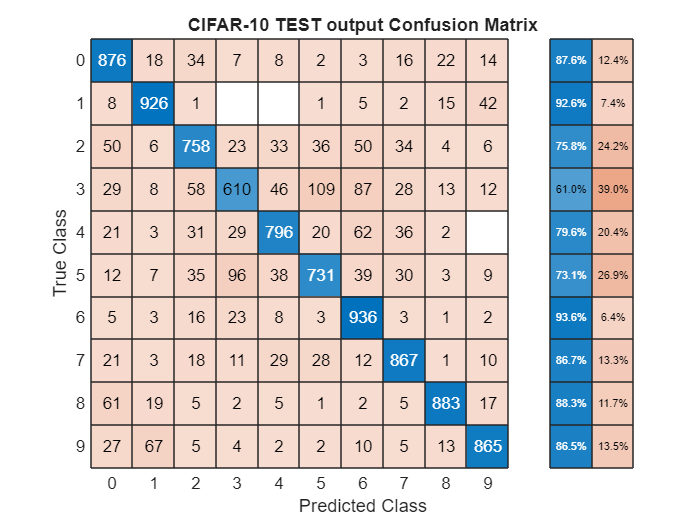

Overall Accuracy (from CM): 82.48%


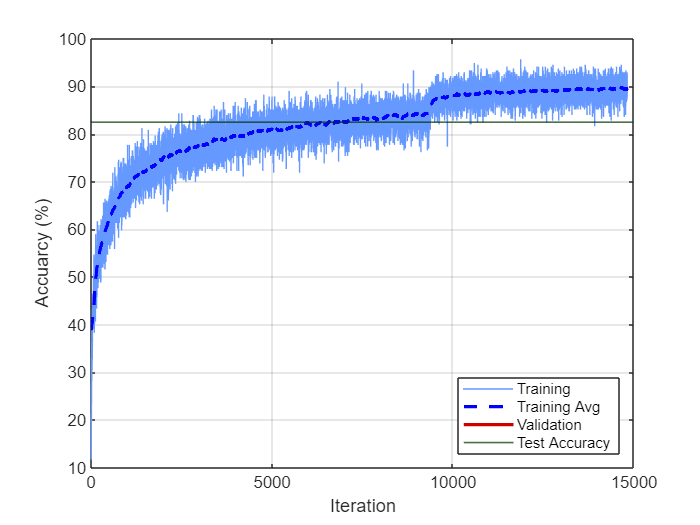

accTest = 82.4800

macroPrecisionTest = 82.4685

macroRecallTest = 82.4800

macroF1Test = 82.2678


=== Running Experiment 2 ===


cfg = struct with fields:
      mm: 'adam'
      lr: 5.0000e-04
      mb: 512
      dr: 80
      mo: 0.9000
    lrdf: 0.1000
      l2: 1.0000e-04
      vp: 30


      mm: 'adam'
      lr: 5.0000e-04
      mb: 512
      dr: 80
      mo: 0.9000
    lrdf: 0.1000
      l2: 1.0000e-04
      vp: 30




=== Running Training 2 ===



=== Done Training 2 ===


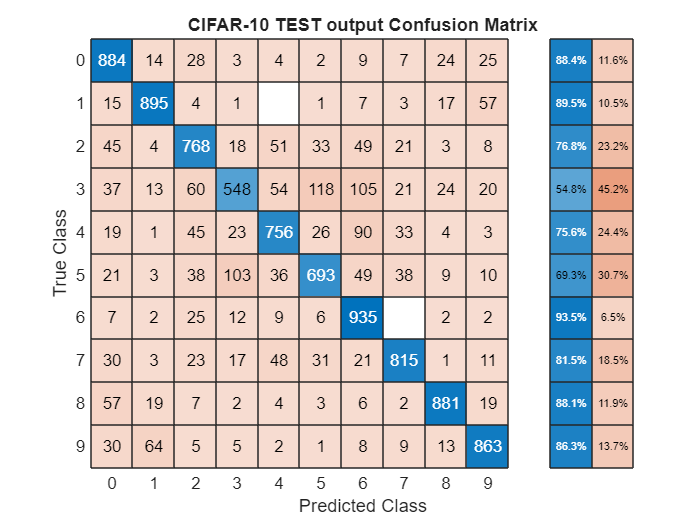

Overall Accuracy (from CM): 80.38%


accTest =          0   80.3800


macroPrecisionTest =          0   80.4640


macroRecallTest =          0   80.3800


macroF1Test =          0   80.0786



=== Running Experiment 3 ===


cfg = struct with fields:
      mm: 'adam'
      lr: 0.0020
      mb: 128
      dr: 30
      mo: 0.9000
    lrdf: 0.5000
      l2: 5.0000e-04
      vp: 25


      mm: 'adam'
      lr: 0.0020
      mb: 128
      dr: 30
      mo: 0.9000
    lrdf: 0.5000
      l2: 5.0000e-04
      vp: 25




=== Running Training 3 ===



=== Done Training 3 ===


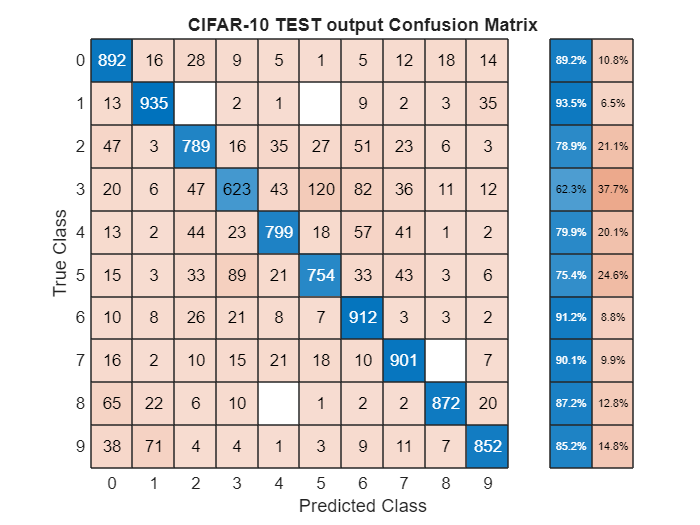

Overall Accuracy (from CM): 83.29%


accTest =          0         0   83.2900


macroPrecisionTest =          0         0   83.3831


macroRecallTest =          0         0   83.2900


macroF1Test =          0         0   83.1236



=== Running Experiment 4 ===


cfg = struct with fields:
      mm: 'adam'
      lr: 1.0000e-03
      mb: 256
      dr: 40
      mo: 0.9000
    lrdf: 0.2000
      l2: 1.0000e-03
      vp: 25


      mm: 'adam'
      lr: 1.0000e-03
      mb: 256
      dr: 40
      mo: 0.9000
    lrdf: 0.2000
      l2: 1.0000e-03
      vp: 25




=== Running Training 4 ===



=== Done Training 4 ===


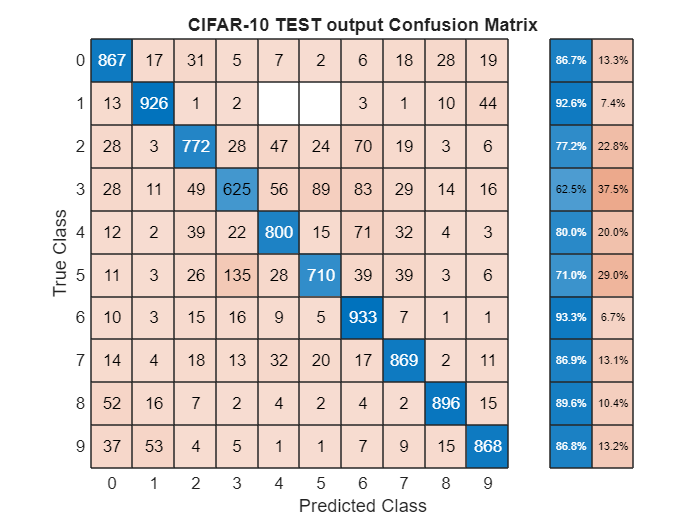

Overall Accuracy (from CM): 82.66%


accTest =          0         0         0   82.6600


macroPrecisionTest =          0         0         0   82.6724


macroRecallTest =          0         0         0   82.6600


macroF1Test =          0         0         0   82.4737



=== Running Experiment 5 ===


cfg = struct with fields:
      mm: 'adam'
      lr: 1.0000e-03
      mb: 128
      dr: 30
      mo: 0.9000
    lrdf: 0.1000
      l2: 1.0000e-04
      vp: 25


      mm: 'adam'
      lr: 1.0000e-03
      mb: 128
      dr: 30
      mo: 0.9000
    lrdf: 0.1000
      l2: 1.0000e-04
      vp: 25




=== Running Training 5 ===



=== Done Training 5 ===


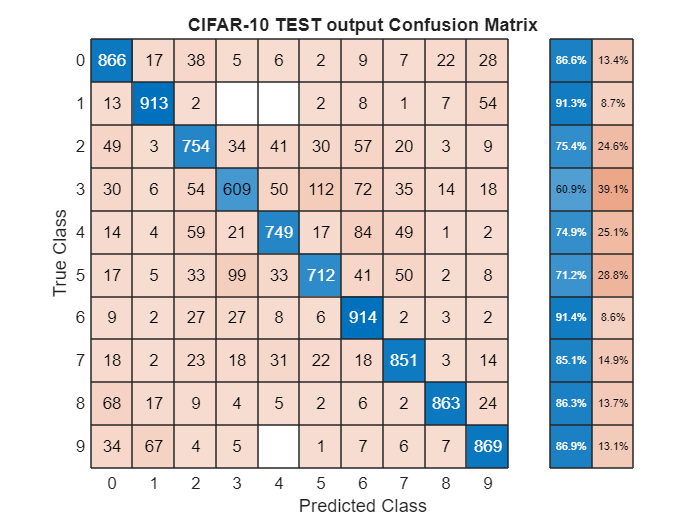

    exportgraphics(figCM, fullfile(outputFolder, sprintf('ConfusionMatrices_Run%d.png',expNum)), 'Resolution', 300);
    exportgraphics(figCM, fullfile(outputFolder, sprintf('ConfusionMatrices_Run%d.pdf',expNum)), 'Resolution', 300);
end

Calculating the mean and Standard deviation

accTest(numRuns+1)            =   mean(accTest(1:numRuns));
macroPrecisionTest(numRuns+1) =   mean(macroPrecisionTest(1:numRuns));
macroRecallTest(numRuns+1)    =   mean(macroRecallTest(1:numRuns));
macroF1Test(numRuns+1)        =   mean(macroF1Test(1:numRuns));
accTest(numRuns+2)            =   std(accTest(1:numRuns));
macroPrecisionTest(numRuns+2) =   std(macroPrecisionTest(1:numRuns));
macroRecallTest(numRuns+2)    =   std(macroRecallTest(1:numRuns));
macroF1Test(numRuns+2)        =   std(macroF1Test(1:numRuns));

% Convert to percentages
accTest            = round(accTest(:), 3);
macroPrecisionTest = round(macroPrecisionTest(:), 3);
macroRecallTest    = round(macroRecallTest(:), 3);
macroF1Test        = round(macroF1Test(:), 3);

% Row names
rowNames = [arrayfun(@(x) sprintf('Run %d', x), 1:numRuns, 'UniformOutput', false), ...
            {'Mean', 'Std'}];

% Create table
resultsTable = table(accTest(:), macroPrecisionTest(:), macroRecallTest(:), macroF1Test(:), ...
    'VariableNames', {'Accuracy(%)', 'Precision(%)', 'Recall(%)', 'F1-score(%)'}, ...
    'RowNames', rowNames);

% Display the table
disp(resultsTable);
